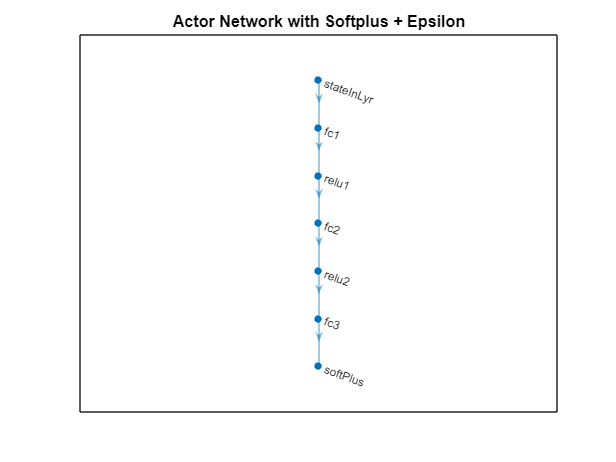

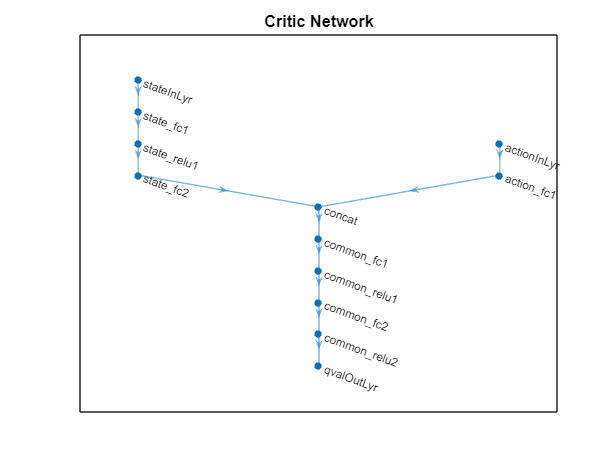

trainingStats =   rlTrainingResult with properties:

           EpisodeIndex: [900×1 double]
          EpisodeReward: [900×1 double]
           EpisodeSteps: [900×1 double]
          AverageReward: [900×1 double]
        TotalAgentSteps: [900×1 double]
           AverageSteps: [900×1 double]
              EpisodeQ0: [900×1 double]
         SimulationInfo: [1×1 rl.storage.SimulationStorage]
    EvaluationStatistic: [900×1 double]
        TrainingOptions: [1×1 rl.option.rlTrainingOptions]


Dot indexing is not supported for variables of this type.

Error in rl.agent.rlTD3Agent/get.Actor_ (line 218)
            actor = this.ExplorationPolicy_.Actor;

Error in rl.agent.rlTD3Agent/getGreedyPolicy_ (line 231)
            policy = rlDeterministicActorPolicy(this.Actor_);

Error in 

Kmin=1

Kmin = 1

epsilon=0.1

epsilon = 0.1000

clear
mdl = 'flexible_joint_v4_rl_Slave_Action_2025';
open_system(mdl)

MAX_EPISODES = 50000;
Ts = 0.01;   % Ts: Sample time (secs)
Tf = 40;   % Tf: Simulation length (secs)
LIMIT_SATURATE=300;
AVERAGE_WINDOW = 10;        % Average over 50 time-steps 
ACCEPTABLE_DELTA = 0.1;
SCALE_ACTION=500;
NOISE_ADD=1;
SCALE_P=1;
SCALE_D=1;


% criticLearningRate = 1e-03;
% actorLearningRate  = 1e-04;
GAMMA = 0.99;
BATCH_SIZE = 512;

obsInfo = rlNumericSpec([10 1],...
    'LowerLimit',[-5 -5 -20 -20 -5 -5 -10 -10 -20 -20]',...
    'UpperLimit',[5 5 20 20 5 5 10 10 20 20]');
obsInfo.Name = 'observations';
obsInfo.Description = 'velocity of links, error, integral of error';
numObservations = obsInfo.Dimension(1);

actInfo = rlNumericSpec([4 1]);
    %  'LowerLimit',[0 0]',...
    % 'UpperLimit',[SCALE_ACTION SCALE_ACTION]');
actInfo.Name = 'additional tue';
numActions = actInfo.Dimension(1);

%blks = [ "flexible_joint_v2_rl_Action_2sh/RL Agent_m", "flexible_joint_v2_rl_Action_2sh/RL Agent_s"];
%obsInfos = {obsInfo,obsInfo};
%actInfos = {actInfo,actInfo};
%env = rlSimulinkEnv(mdl,blks,obsInfos,actInfos);
env = rlSimulinkEnv(mdl,[mdl '/RL Agent_s'],obsInfo,actInfo);

%env = rlSimulinkEnv(mdl,[mdl '/RL Agent'],obsInfo,actInfo);
env.ResetFcn = @(in)localResetFcn(in, mdl);


agentOpts_s = rlTD3AgentOptions(SampleTime=Ts, ...
    DiscountFactor=GAMMA, ...
    ExperienceBufferLength=1e7, ...
    MiniBatchSize=BATCH_SIZE);

% Critic optimizer options
for idx = 1:2
    agentOpts_s.CriticOptimizerOptions(idx).LearnRate = 1e-4;
    agentOpts_s.CriticOptimizerOptions(idx).GradientThreshold = 1;
end

% Actor optimizer options
agentOpts_s.ActorOptimizerOptions.LearnRate = 1e-4;
agentOpts_s.ActorOptimizerOptions.GradientThreshold = 1;

agentOpts_s.ExplorationModel.StandardDeviationMin = 0.05;
agentOpts_s.ExplorationModel.StandardDeviation =4;
agentOpts_s.ExplorationModel.StandardDeviationDecayRate = 1e-7;

% Define the state path for the critic network
statePath = [
    featureInputLayer(numObservations, Name='stateInLyr')
    fullyConnectedLayer(128, Name='state_fc1')
    reluLayer(Name='state_relu1')
    fullyConnectedLayer(64, Name='state_fc2')
    ];

% Define the action path for the critic network
actionPath = [
    featureInputLayer(numActions, Name='actionInLyr')
    fullyConnectedLayer(64, Name='action_fc1')
    ];

% Define the common path for the critic network
commonPath = [
    concatenationLayer(1, 2, Name='concat')
    fullyConnectedLayer(60, Name='common_fc1')
    reluLayer(Name='common_relu1')
    fullyConnectedLayer(36, Name='common_fc2')
    reluLayer(Name='common_relu2')
    fullyConnectedLayer(1, Name='qvalOutLyr') % Single output neuron for Q-value
    ];

% Create the critic network
criticNet = layerGraph();
criticNet = addLayers(criticNet, statePath);
criticNet = addLayers(criticNet, actionPath);
criticNet = addLayers(criticNet, commonPath);

% Connect layers in the critic network
criticNet = connectLayers(criticNet, 'state_fc2', 'concat/in1');
criticNet= connectLayers(criticNet, 'action_fc1', 'concat/in2');


% Convert the neural network to a dlnetwork object without initializing the networks
criticdlNet_s = dlnetwork(criticNet, Initialize=false);
critic_s1 = rlQValueFunction(initialize(criticdlNet_s), obsInfo, actInfo);
critic_s2 = rlQValueFunction(initialize(criticdlNet_s), obsInfo, actInfo);

% Define the actor network
actorNet = [
    featureInputLayer(numObservations, Name='stateInLyr')
    fullyConnectedLayer(128, Name='fc1')
    reluLayer(Name='relu1')
    fullyConnectedLayer(64, Name='fc2')
    reluLayer(Name='relu2')
    fullyConnectedLayer(numActions, Name='fc3')
    softplusLayer(Name='softPlus')
    %softplusEpsilonLayer(epsilon, 'softplusEpsilonLayer') % Softplus + epsilon
    ];

% Convert to a dlnetwork
actordlNet_s = dlnetwork(actorNet);
% Visualize the Actor Network
actorLayerGraph = layerGraph(actordlNet_s.Layers);
figure;
plot(actorLayerGraph);
title('Actor Network with Softplus + Epsilon');


actor_s = rlContinuousDeterministicActor(actordlNet_s, obsInfo, actInfo);

%%%%%% ploting
% Visualizing the Actor Network
%figure;
%plot(actorNet);
%title('Actor Network');

% Visualizing the Critic Network
figure;
plot(criticNet);
title('Critic Network');

agent_s = rlTD3Agent(actor_s,[critic_s1,critic_s2], agentOpts_s);

trainOpts = rlTrainingOptions(...
    'MaxEpisodes', MAX_EPISODES, ...
    'MaxStepsPerEpisode', ceil(Tf/Ts), ...
    'ScoreAveragingWindowLength', AVERAGE_WINDOW, ...
    'Verbose', true, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','None');



trainOpts.UseParallel = true;
trainOpts.ParallelizationOptions.Mode = 'async';

%trainingStats = train(agent_s, env, trainOpts);

trainingStats

%save("Adaptive_4_Gians_PDdfdgfdg_randomized_20sh_withIAE_FINAL_FINAL_FINAL.mat","agent_s")
load("Adaptive_4_Gians_PDd_randomized_20sh_withIAE_FINAL_FINAL_FINAL.mat","agent_s")


simOpts = rlSimulationOptions(MaxSteps=ceil(Tf/Ts));
experiences = sim(env,agent_s,simOpts);

actor = getActor(agent_s);
parameters = getLearnableParameters(actor)
parameters{1}

function in = localResetFcn(in, mdl)
    margin=0.5;
    % Set random gain for gain_1
    tau_h_gain_1 = strcat(mdl, '/MASTER/tauh/Gain1');
    
    % Decide which range to use for gain_1 (0 for negative range, 1 for positive range)
    range_choice1 = randi([0, 1]);
    if range_choice1 == 0
        % Generate a number between -1 and -0.8
        random_gain_1 = -1 + (margin * rand);
    else
        % Generate a number between 0.8 and 1
        random_gain_1 = (1-margin) + (margin * rand);
    end

    % Set random gain for gain_2
    tau_h_gain_2 = strcat(mdl, '/MASTER/tauh/Gain2');
    
    % Decide which range to use for gain_2 (0 for negative range, 1 for positive range)
    range_choice2 = randi([0, 1]);
    if range_choice2 == 0
        % Generate a number between -1 and -0.7
        random_gain_2 = -1 + (margin * rand);
    else
        % Generate a number between 0.7 and 1
        random_gain_2 = (1-margin) + (margin * rand);
    end
  

    delay_m_gain = strcat(mdl, '/Delay Master/delay_m/Gain_delay_m');
    delay_s_gain = strcat(mdl, '/Delay Slave/delay_s/Gain_delay_s');
    random_gain_delay_m = (1-margin) + (margin * rand);
    random_gain_delay_s = (1-margin) + (margin * rand);
      % Set the block parameters with the generated gains
    in = setBlockParameter(in, tau_h_gain_1, 'Gain', num2str(random_gain_1));
    in = setBlockParameter(in, tau_h_gain_2, 'Gain', num2str(random_gain_2));
    in = setBlockParameter(in, delay_m_gain, 'Gain', num2str(random_gain_delay_m));
    in = setBlockParameter(in, delay_s_gain, 'Gain', num2str(random_gain_delay_s));
    
end



function in = localResetFcn2(in, mdl)
    
end

